path = 'Unziped/A5_20190604/fichier3';
extension = 'npy';
folderlist = dir([path,'/*',extension]);
% Déclaration d'une structure pour stocker les variables
data = struct();

% Boucle pour traiter chaque fichier
for ifile = 1:length(folderlist)
    % Affichage du nom de fichier sans l'extension
    filename = folderlist(ifile).name(1:(length(folderlist(ifile).name)-4));
    disp(filename);
    
    % Lecture des données du fichier
    filepath = fullfile(path, folderlist(ifile).name);
    data.(filename) = readNPY(filepath);
end

MarkOnSignal
SampleRate
firstsignal
mark
signal
timestamp


electrodes = data.signal(:,[3,14,16,18]);

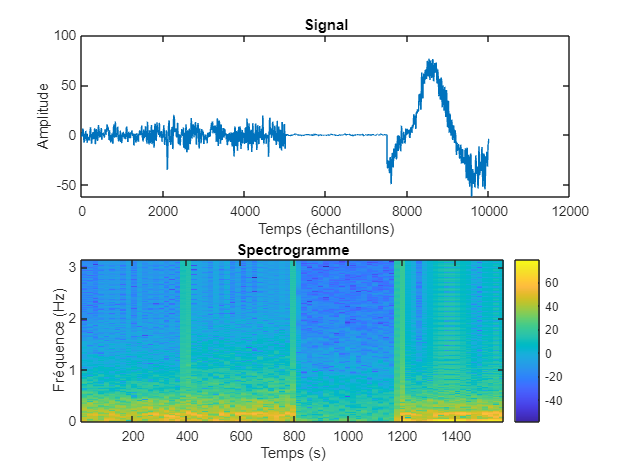

%Droite

signal = [electrodes(27600:30100,1);...
    electrodes(27600:30100,2);...
    electrodes(27600:30100,3);...
    electrodes(27600:30100,4)];

% Définir les paramètres pour le spectrogramme
windowSize = 256; % Taille de la fenêtre
overlap = windowSize/2; % Recouvrement entre les fenêtres
fftSize = 1024; % Taille de la FFT

% Calculer le spectrogramme
[s, f, t] = spectrogram(signal, windowSize, overlap, fftSize);

% Tracer le signal et le spectrogramme sur la même figure
figure;
subplot(2,1,1);
plot(signal);
title('Signal');
xlabel('Temps (échantillons)');
ylabel('Amplitude');
subplot(2,1,2);
imagesc(t, f, 20*log10(abs(s)));
axis xy;
title('Spectrogramme');
xlabel('Temps (s)');
ylabel('Fréquence (Hz)');
colorbar;

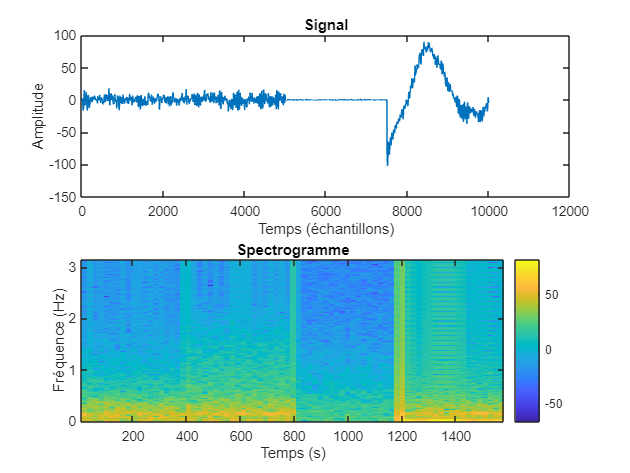

%Gauche

signal2 = [electrodes(23100:25600,1);...
    electrodes(23100:25600,2);...
    electrodes(23100:25600,3);...
    electrodes(23100:25600,4)];
% Définir les paramètres pour le spectrogramme
windowSize = 256; % Taille de la fenêtre
overlap = windowSize/2; % Recouvrement entre les fenêtres
fftSize = 1024; % Taille de la FFT

% Calculer le spectrogramme
[s, f, t] = spectrogram(signal2, windowSize, overlap, fftSize);

% Tracer le signal et le spectrogramme sur la même figure
figure;
subplot(2,1,1);
plot(signal2);
title('Signal');
xlabel('Temps (échantillons)');
ylabel('Amplitude');
subplot(2,1,2);
imagesc(t, f, 20*log10(abs(s)));
axis xy;
title('Spectrogramme');
xlabel('Temps (s)');
ylabel('Fréquence (Hz)');
colorbar;

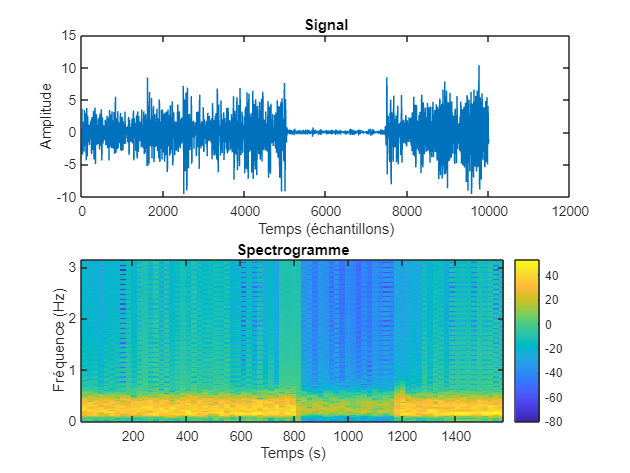

% Droite
fs = 500; %fréquence d'échantillonnage
fc = 35;
[b,a] = butter(4,fc/(fs/2),"low"); %filtre passe-bas (supprimer bruit à haute fréquence)
eeg_data_filtered = filtfilt(b,a,signal); % appliquer filtre aux données EEG

fc = 12 ;
[b,a] = butter(4,fc/(fs/2),"high"); %filtre passe-haut (supprimer bruit à basse fréquence)
eeg_data_filtered = filtfilt(b,a, eeg_data_filtered);

% Définir les paramètres pour le spectrogramme
windowSize = 256; % Taille de la fenêtre
overlap = windowSize/2; % Recouvrement entre les fenêtres
fftSize = 1024; % Taille de la FFT

% Calculer le spectrogramme
[s, f, t] = spectrogram(eeg_data_filtered, windowSize, overlap, fftSize);

% Tracer le signal et le spectrogramme sur la même figure
figure;
subplot(2,1,1);
plot(eeg_data_filtered);
title('Signal');
xlabel('Temps (échantillons)');
ylabel('Amplitude');
subplot(2,1,2);
imagesc(t, f, 20*log10(abs(s)));
axis xy;
title('Spectrogramme');
xlabel('Temps (s)');
ylabel('Fréquence (Hz)');
colorbar;

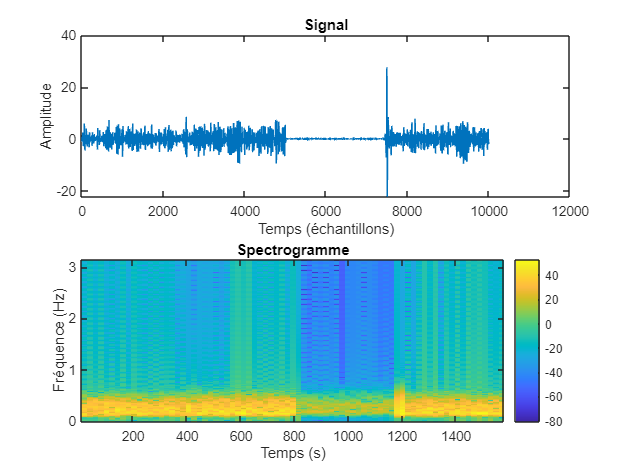

% Gauche
fs = 500; %fréquence d'échantillonnage
fc = 35;
[b,a] = butter(4,fc/(fs/2),"low"); %filtre passe-bas (supprimer bruit à haute fréquence)
eeg_data_filtered = filtfilt(b,a,signal2); % appliquer filtre aux données EEG

fc = 12 ;
[b,a] = butter(4,fc/(fs/2),"high"); %filtre passe-haut (supprimer bruit à basse fréquence)
eeg_data_filtered = filtfilt(b,a, eeg_data_filtered);

% Définir les paramètres pour le spectrogramme
windowSize = 256; % Taille de la fenêtre
overlap = windowSize/2; % Recouvrement entre les fenêtres
fftSize = 2048; % Taille de la FFT

% Calculer le spectrogramme
[s, f, t] = spectrogram(eeg_data_filtered, windowSize, overlap, fftSize);

% Tracer le signal et le spectrogramme sur la même figure
figure;
subplot(2,1,1);
plot(eeg_data_filtered);
title('Signal');
xlabel('Temps (échantillons)');
ylabel('Amplitude');
subplot(2,1,2);
imagesc(t, f, 20*log10(abs(s)));
axis xy;
title('Spectrogramme');
xlabel('Temps (s)');
ylabel('Fréquence (Hz)');
colorbar;

% filtrage signal par signal
% sig_final = 0;
% for ele = 1:4
%     fs = 500; %fréquence d'échantillonnage
%     fc = 35;
%     [b,a] = butter(4,fc/(fs/2),"low"); %filtre passe-bas (supprimer bruit à haute fréquence)
%     eeg_data_filtered = filtfilt(b,a,electrodes(23100:25600,ele)); % appliquer filtre aux données EEG
%     
%     fc = 12 ;
%     [b,a] = butter(4,fc/(fs/2),"high"); %filtre passe-haut (supprimer bruit à basse fréquence)
%     eeg_data_filtered = filtfilt(b,a, eeg_data_filtered);
%     sig_final = [sig_final;eeg_data_filtered];
% end
% sig_final = sig_final(2:length(sig_final));
% % aucune différence observée lors de la comparaison du filtrage du signal final 
% % et du filtrage signal par signal (voir ci dessous)
% plot(sig_final) 

Aucune différence observée lors de la comparaison du filtrage du signal final et du filtrage signal par signal (voir ci dessus). On va donc choisir de tracer le scalogramme en filtrant le signal final (les signaux des quatres électrodes réunis).

### Scalogrammes

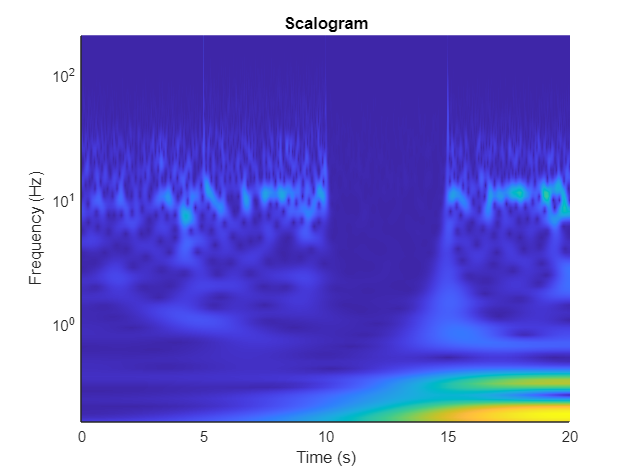

%
% Tracé du scalogrmme sans filtrage préalable
%
% Concaténation des signaux des différentes électrodes
sig = [electrodes(27600:30100,1);...
    electrodes(27600:30100,2);...
    electrodes(27600:30100,3);...
    electrodes(27600:30100,4)];
% Transformée en ondelettes du signal
fb = cwtfilterbank(signallength = length(sig),...
    samplingfrequency=500, ...
    wavelet="Morse");
[cfs,frq] = wt(fb,sig);
t = (0:(length(sig)-1))/500;
h = figure;
pcolor(t,frq,abs(cfs));
set(gca,'yscale','log');shading interp;axis tight;
title('Scalogram');xlabel('Time (s)');ylabel('Frequency (Hz)');

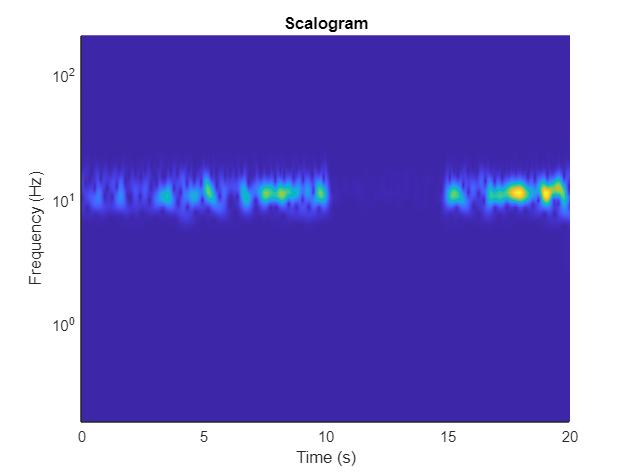

%
% Tracé du scalogramme après filtrage du signal
%
% Concaténation des signaux des différentes électrodes
sig = [electrodes(27600:30100,1);...
    electrodes(27600:30100,2);...
    electrodes(27600:30100,3);...
    electrodes(27600:30100,4)];
fs = 500; %fréquence d'échantillonnage
fc1 = 35;
[b,a] = butter(4,fc/(fs/2),"low"); %filtre passe-bas (supprimer bruit à haute fréquence)
eeg_data_filtered = filtfilt(b,a,sig); % appliquer filtre aux données EEG

fc2 = 12 ;
[b,a] = butter(4,fc/(fs/2),"high"); %filtre passe-haut (supprimer bruit à basse fréquence)
eeg_data_filtered = filtfilt(b,a, eeg_data_filtered);

% Transformée en ondelettes du signal
fb = cwtfilterbank(signallength = length(eeg_data_filtered),...
    samplingfrequency=fs, ...
    wavelet="Morse");
[cfs,frq] = wt(fb,eeg_data_filtered);

% 
t = (0:(length(eeg_data_filtered)-1))/fs;
h = figure;
pcolor(t,frq,abs(cfs));
set(gca,'yscale','log');shading interp;axis tight;
title('Scalogram');xlabel('Time (s)');ylabel('Frequency (Hz)');

## Récupération de signaux 

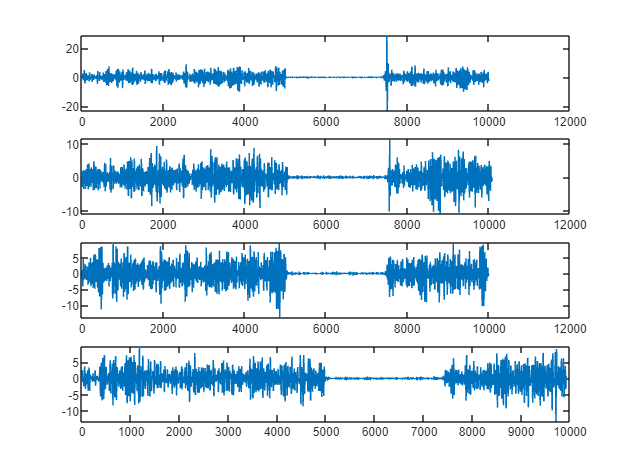

fc2=12;
fc1=35;
Fs=500;

sig1 = [electrodes(23100:25600,1);...
    electrodes(23100:25600,2);...
    electrodes(23100:25600,3);...
    electrodes(23100:25600,4)];
[b,a] = butter(4,[fc2 fc1]/(Fs/2)); %filtre passe-bande
eeg_data_filtered1 = filtfilt(b,a,sig1); % appliquer filtre au signal

sig2 = [electrodes(45580:48100,1);...
    electrodes(45580:48100,2);...
    electrodes(45580:48100,3);...
    electrodes(45580:48100,4)];
[b,a] = butter(4,[fc2 fc1]/(Fs/2)); %filtre passe-bande
eeg_data_filtered2 = filtfilt(b,a,sig2); % appliquer filtre au signal

sig3 = [electrodes(59100:61600,1);...
    electrodes(59100:61600,2);...
    electrodes(59100:61600,3);...
    electrodes(59100:61600,4)];
[b,a] = butter(4,[fc2 fc1]/(Fs/2)); %filtre passe-bande
eeg_data_filtered3 = filtfilt(b,a,sig3); % appliquer filtre au signal

sig4 = [electrodes(68100:70580,1);...
    electrodes(68100:70580,2);...
    electrodes(68100:70580,3);...
    electrodes(68100:70580,4)];
[b,a] = butter(4,[fc2 fc1]/(Fs/2)); %filtre passe-bande
eeg_data_filtered4 = filtfilt(b,a,sig4); % appliquer filtre au signal
figure(1)
subplot(411);
plot(eeg_data_filtered1);
subplot(412)
plot(eeg_data_filtered2)
subplot(413)
plot(eeg_data_filtered3)
subplot(414);
plot(eeg_data_filtered4)